**Create the shape**

% fig = plot(projected_grid(shadow,1),projected_grid(shadow,3));
% linkdata on
folder = 'STLs';
stls = dir(folder)

stls = 14×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


Currently rotating: 3DPrint.stl


Currently rotating: 6489golevka.stl


Currently rotating: Airbus_A321_Air_Canada.stl


Currently rotating: Belisana Model 1.stl


Currently rotating: Daphne Carry 2019.stl


Currently rotating: Eros Gaskell 200k poly.stl


Currently rotating: Geographos LightCurve (1).stl


Currently rotating: Hygiea Vernazza 2018.stl


Currently rotating: Interamnia Hanus.stl


Currently rotating: Itokawa Radar.stl


Currently rotating: Tempel Durech.stl


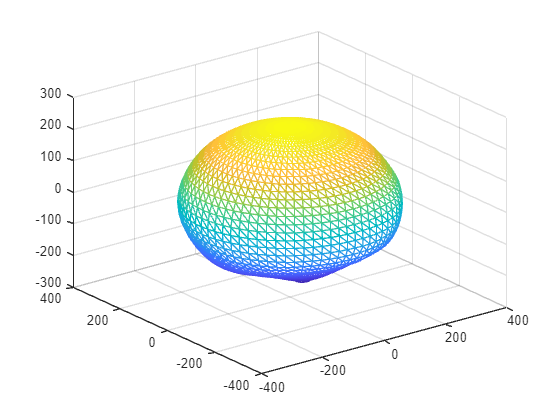

Currently rotating: Vesta Optical.stl


pos = 0;
results = zeros(size(stls,1),3,'double');
for file = stls'
    if file.isdir == 1
        continue;
    end
    pos = pos+1;
    importstl = stlread(folder + "\" + file.name);
    s = trimesh(importstl);
    disp("Currently rotating: " + file.name)

**Setup**

    po = [0 0 0]; % point of our plane, here simply the origin
    no = [0 1 0]; % normal vector of the plane i.e. pointing along the y-axis
    num = 10000;
    areas = zeros(num,1,'double');
    g = [0 0 0];
    beta = 0;

**Get a random uniform sample of *****num***** points on a sphere. **(https://uk.mathworks.com/matlabcentral/fileexchange/37004-suite-of-functions-to-perform-uniform-sampling-of-a-sphere)

    tic
    % V=RandSampleSphere(num,'stratified');
    % [V,Tri]=SpiralSampleSphere(num,'false');

**Run the rotation using the previously acquired points on a sphere.**

    % for k = 1:length(V)

**Get x-z projection of the shapegss**

    %     % refreshdata
    %     % drawnow %draw the rotation
    %     %get data as a result of rotation
    %     XX = s.Vertices(:,1);
    %     YY = s.Vertices(:,2);
    %     ZZ = s.Vertices(:,3);
    %     % concat the shape grid
    %     gr = [XX(:) YY(:) ZZ(:)];
    %     v = gr - repmat(po,numel(XX(:)),1);
    %     % dot vector with the normal vector of the plane of intrest
    %     % this represents the distance from the grid points to our plane along the normal
    %     d = v(:,1)*no(1) + v(:,2)*no(2) + v(:,3)*no(3); 
    %     % get the projected points
    %     projected_grid = gr - d .* repmat(no,numel(XX(:)),1);
    %     projected_grid = unique(projected_grid,'rows','stable');
    %     %we need the outer points of the region, acquire this and the area of
    %     %the region with convex hull.
    %     [shadow,ar] = convhull(projected_grid(:,1),projected_grid(:,3));              
    %     areas(k) = ar;

**Rotate the shape**

    %     a = [V(k,1), V(k,2), 0];
    %     b = [0 0 2];
    %     if norm(g)==0; g = cross(a,b); continue; end %if the magnitude of the cross product is zero, then continue to the next iteration
    % 
    %     rotate(s,g,rad2deg(beta));
    %     g = 2*cross(a,b); %find the cross product between a and b
    %     beta = acos(V(k,3));
    %     rotate(s,g,-rad2deg(beta));
    % 
    %     plot(projected_grid(shadow,1),projected_grid(shadow,3));
    %     hold off;
    %     xlim([-1000 1000]);ylim([-1000 1000]);zlim([-1000 1000]);
    %     drawnow %to display the rotation
    %  end
    results(pos,1) = surfaceArea(alphaShape(s.Vertices));
    results(pos,2) = mean(areas);
    results(pos,3) = results(pos,2)/results(pos,1);
    results

results = 1.0e+05 *

    7.1118         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


results = 1.0e+05 *

    7.1118         0         0
    0.0002         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


results = 1.0e+05 *

    7.1118         0         0
    0.0002         0         0
    0.0096         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


results = 1.0e+05 *

    7.1118         0         0
    0.0002         0         0
    0.0096         0         0
    0.0001         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


results = 1.0e+05 *

    7.1118         0         0
    0.0002         0         0
    0.0096         0         0
    0.0001         0         0
    1.8879         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


results = 1.0e+05 *

    7.1118         0         0
    0.0002         0         0
    0.0096         0         0
    0.0001         0         0
    1.8879         0         0
    0.0224         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


results = 1.0e+05 *

    7.1118         0         0
    0.0002         0         0
    0.0096         0         0
    0.0001         0         0
    1.8879         0         0
    0.0224         0         0
    0.0001         0         0
         0         0         0
         0         0         0
         0         0         0


results = 1.0e+06 *

    0.7112         0         0
    0.0000         0         0
    0.0010         0         0
    0.0000         0         0
    0.1888         0         0
    0.0022         0         0
    0.0000         0         0
    1.1003         0         0
         0         0         0
         0         0         0


results = 1.0e+06 *

    0.7112         0         0
    0.0000         0         0
    0.0010         0         0
    0.0000         0         0
    0.1888         0         0
    0.0022         0         0
    0.0000         0         0
    1.1003         0         0
    0.6562         0         0
         0         0         0


results = 1.0e+06 *

    0.7112         0         0
    0.0000         0         0
    0.0010         0         0
    0.0000         0         0
    0.1888         0         0
    0.0022         0         0
    0.0000         0         0
    1.1003         0         0
    0.6562         0         0
    0.0000         0         0


results = 1.0e+06 *

    0.7112         0         0
    0.0000         0         0
    0.0010         0         0
    0.0000         0         0
    0.1888         0         0
    0.0022         0         0
    0.0000         0         0
    1.1003         0         0
    0.6562         0         0
    0.0000         0         0


results = 1.0e+06 *

    0.7112         0         0
    0.0000         0         0
    0.0010         0         0
    0.0000         0         0
    0.1888         0         0
    0.0022         0         0
    0.0000         0         0
    1.1003         0         0
    0.6562         0         0
    0.0000         0         0


    disp("Time taken to run: "+toc+' seconds')

Time taken to run: 2.5492 seconds


Time taken to run: 0.054841 seconds


Time taken to run: 0.15523 seconds


Time taken to run: 0.049008 seconds


Time taken to run: 0.012267 seconds


Time taken to run: 2.0456 seconds


Time taken to run: 0.012694 seconds


Time taken to run: 0.01242 seconds


Time taken to run: 0.009012 seconds


Time taken to run: 0.034679 seconds


Time taken to run: 0.0099724 seconds


Time taken to run: 0.026359 seconds


end